# Linear Transformations of Random Variables

## Introduction

If $X$ is a random variable and if $a$ and $b$ are any constants, then $a + bX$ is a **linear transformation** of $X$. It scales $X$ by $b$ and shifts it by $a$. 

A linear transformation of $X$ is another random variable; we often denote it by Z


$$Z = a+b X$$


Suppose to know both the mean value $\text{E}[X]$ and the variance $\sigma^{2}_{X}$ of the r.v. $X$. What are the corresponding mean value and variance of the r.v. $Z$?

## Expected Value of a Linearly Transformed Random Variable

Given a random variable $X$ such that


$$\text{E} \left[X\right] = \mu_{X}$$


and considering the linear transformation


$$Z = a+b\cdot X \quad a\,,\;b \in \mathbb{R}$$


then


$$\text{E}\left[Z \right] = \text{E}\left[a+b\cdot X\right] = a+b\cdot \text{E}\left[X\right] \quad \Longrightarrow \quad \text{E}\left[Z \right] = a+b\cdot \mu_{X}$$


Thus, the expected value of a linear transformation of a r.v. $X$ is just the linear transformation of the expected value of $X$.

## Variance of a Linearly Transformed Random Variable

Applying the definition of variance for the r.v. $Z$ we get


$$\text{var} \left[Z\right] = \text{E} \left[ \left(z-\mu_{Z}\right)^{2} \right] = \text{E} \left[\left(a+bx-a-b\mu_{X}\right)^{2}\right] = \text{E} \left[b^2 \left(x-\mu_X\right)^2\right] \quad \Longrightarrow \quad \sigma^2_{Z} = b^2\cdot \sigma^2_{X}$$


**Remark**: the variance of $a + bX$ does not depend on $a$. This is appropriate: the variance is a measure of spread; adding $a$ does not change the spread, it merely shifts the distribution to the left or to the right. It is $b$ th responsible of changing the spread.

## Applying Linear Transformation to Random Variables in MATLAB

A linear transformation of a random variable is the simplest method to obtain a r.v.  with desired expected value and variance, given a r.v. with zero as mean value and one as the variance.

clear
close all
clc

### An Uniform Random Variable

For example,  a r.v. with (-5) as the mean value, the value +10 as the variance and distributed according the **uniform distribution** can be obtained in MATLAB using the command

muZ = -5; % the desired mean value
sigmaZ = +10; % the desired variance
N = 10000; % how many samples?
% the linear transformation
Z = muZ+sqrt(12*sigmaZ)*(rand(N,1)-0.5); % <-- the data

Please, verify experimentally that the expected value and variance of the sequence of random variables are as expected.

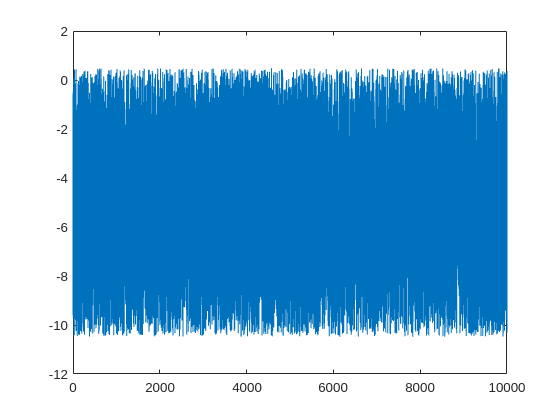

% write a piece of code for estimating the average value and the sample
% variance of the sequence
plot(Z)

### A Gaussian Radom Variable

Suppose now to generate a **gaussian r.v**. with (-5) as the mean value, and the value +10 as the variance. The MATLAB code is

muY = -5; % the desired mean value
sigmaY = +10; % the desired variance
N = 10000; % how many samples?
% the linear transformation
Y = muY+sqrt(sigmaY)*randn(N,1); % <-- the data

Please, verify experimentally that the expected value and variance of the sequence of random variables are as expected.

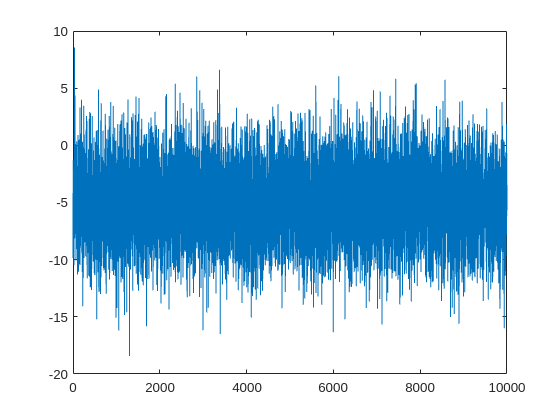

% write a piece of code for estimating the average value and the sample
% variance of the sequence
plot(Y)